X = [-0.82444207 -1.85397676  1.33441263  0.69983175]';
Y = [ 0.53437239 -0.67975135 -0.67860957  0.53867252]';
Z = [1.50532344 3.14244214 3.10493527 1.58105604]';


A = [ones(length(X), 1), X, Y];
coeffs = A \ Z

coeffs =     2.2408
    0.0007
   -1.3001



x_mag = 1/sqrt(1+coeffs(2)^2);
y_mag = 1/sqrt(1+coeffs(3)^2);
x_basis = [x_mag, 0, coeffs(2)*x_mag];
y_basis = [0, y_mag, coeffs(3)*y_mag];

syms x y
z = coeffs(1) + x * coeffs(2) + y * coeffs(3);


P = [X';Y';Z'];
p_on_x = x_basis*(P - [0 0 coeffs(1)]');
p_proj_x = x_basis'*p_on_x;
p_on_y = y_basis*(P - [0 0 coeffs(1)]');
p_proj_y = y_basis'*p_on_y;

x_min_c = min(p_on_x);
x_max_c = max(p_on_x);
y_min_c = min(p_on_y);
y_max_c = max(p_on_y);
bounds_x_c = [x_min_c x_min_c x_max_c x_max_c, x_min_c];
bounds_y_c = [y_min_c y_max_c y_max_c y_min_c, y_min_c];
bound_points = x_basis'*bounds_x_c+y_basis'*bounds_y_c+[0 0 coeffs(1)]';
x_min = min(bound_points(:, 1))

x_min = -1.8533

y_min = min(bound_points(:, 2))

y_min = -1.8533

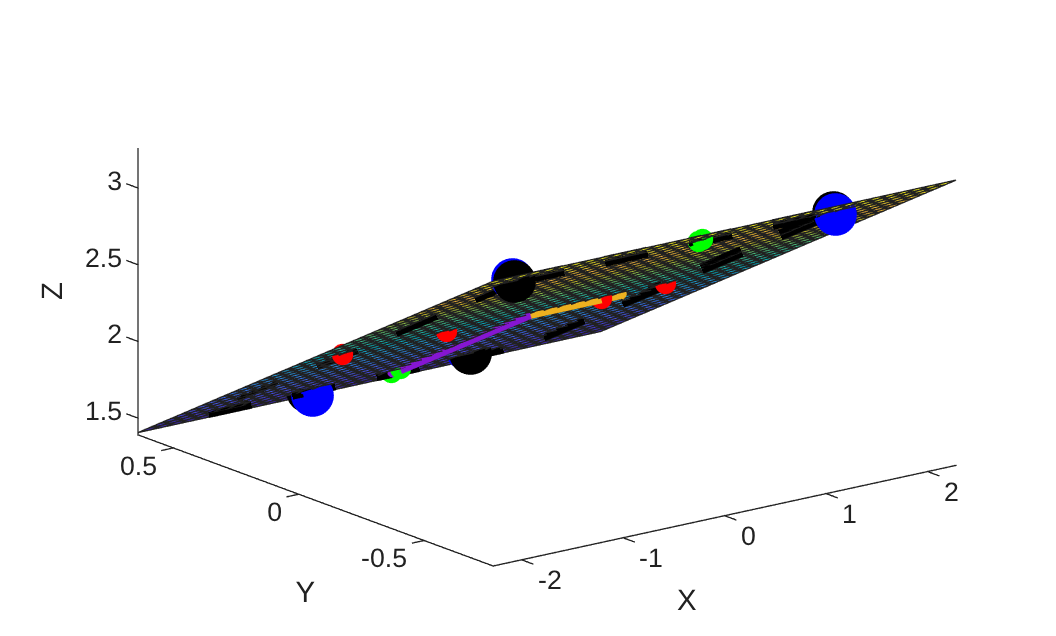

x_range_c = x_max_c - x_min_c;
x_range = norm(x_basis'*x_range_c);
y_range_c = y_max_c - y_min_c;
y_range = norm(y_basis'*y_range_c);

x_pixles = 1000;
y_pixles = x_pixles * (y_range / x_range);

x_pix =  ( p_on_x - x_min_c ) ./ x_range_c .* x_pixles;
y_pix =  ( p_on_y - y_min_c ) ./ y_range_c .* y_pixles;

figure
plot3(X, Y, Z, ".b", "MarkerSize", 48);
hold on
fsurf(z)
quiver3(0, 0, coeffs(1), x_basis(1), x_basis(2), x_basis(3), "LineWidth", 4)
quiver3(0, 0, coeffs(1), y_basis(1), y_basis(2), y_basis(3), "LineWidth", 4)
xlabel("X")
ylabel("Y")
zlabel("Z")
plot3(p_proj_x(1, :), p_proj_x(2, :),p_proj_x(3, :)+coeffs(1), '.r', 'MarkerSize', 24)
plot3(p_proj_y(1, :), p_proj_y(2, :),p_proj_y(3, :)+coeffs(1), '.g', 'MarkerSize', 24)
plot3(p_proj_x(1, :), p_proj_y(2, :),p_proj_x(3, :)+p_proj_y(3, :)+coeffs(1), '.k', 'MarkerSize', 48)
plot3(bound_points(1, :), bound_points(2, :), bound_points(3, :), '--k', 'LineWidth',4)

axis padded